# Analytical Approach to Derive Equations of Motion

This script provides a systematic approaching for deriving equations of motion using the Lagrange analytical dynamics approach for a system without constraints. The problem in focus is for a brick rod system from project 3.

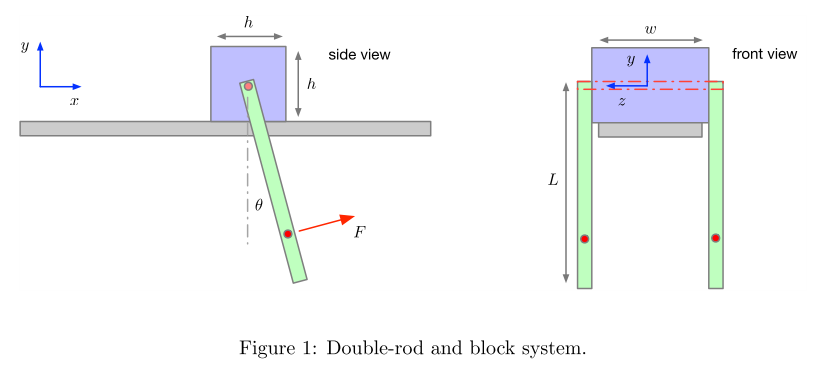

% cleanup
clc,clear,close all
sympref('default');         % cleanup symbolic preferences

## Variable Definitions

### Notation

In order to make use of symbolic math features in MATLAB, variables involved in the problem are defined here in three different manners.

- Variables ending with the letter "T" (capitalized) represent the **time** version of this variable. These are useful when differentiating variables with respect to time. See below for an example

syms fT(t)
fT

$$fT(t) = \mathrm{fT}\left(t\right)$$

dfT = diff(fT,t)

$$dfT(t) = \frac{\partial }{\partial t}\mathrm{fT}\left(t\right)$$

- Variable ending with the letter "S" (capitalized) represent the **symbolic** version of this variable. These are helpful when differentiating variables with respect to variables other than time. For example

syms fS
fS

$$fS = \mathrm{fS}$$

dfS = sym('dfS')

$$dfS = \mathrm{dfS}$$

y = fS^2 + dfS*sin(fS);
diff(y,fS)

$$ans = 2\,\mathrm{fS}+\mathrm{dfS}\,\cos\left(\mathrm{fS}\right)$$

- Variables in neither of these categories will have no significant ending letter. This includes vector definitions as well. For example

syms L
L

$$L = L$$

clear

### Usage and Substitutions

The purpose for using the notation described above is for substitutions to be made that allow proper computations regarding the Lagrange derivation. For example, in the Lagrange equation (no constraints) $\frac{d}{dt}\left(\frac{\partial L}{\partial \dot{q}_i}\right) - \frac{\partial L}{\partial q_i} = Q_i$ there are derivatives with respect to (WRT) the generalized coordinates and time. Each of these processes require something different from symbolic computation. WRT generalized coordinates, the **symbolic** version of variables are used. WRT time, the **time** version of variables are used. See the illustration below.

First, all the variables are defined with the notation from above.

% define time versions of variables
syms xT(t) yT(t) zT(t)
xdT = diff(xT,t);
ydT = diff(yT,t);
zdT = diff(zT,t);
xddT = diff(xT,t,2);
yddT = diff(yT,t,2);
zddT = diff(zT,t,2);
varT = [xT, yT, zT, xdT, ydT, zdT, xddT, yddT, zddT];       % vector of time version variables

% define symbolic versions of variables
syms xS yS zS xdS ydS zdS xddS yddS zddS
varS = [xS, yS, zS, xdS, ydS, zdS, xddS, yddS, zddS];       % vector of symbolic version variables


% define other variables
syms L g m

Then, some vectors are created that will are differentiated WRT **time** and **symbolic**. Some substitutions are made to show illustrate this workflow.

r1T = [xT*xdT+sin(xT);
      yT;
      zT]                       % position like vector

$$r1T(t) = \left(\begin{array}{c} \mathrm{xT}\left(t\right)\,\frac{\partial }{\partial t}\mathrm{xT}\left(t\right)+\sin\left(\mathrm{xT}\left(t\right)\right)\\ \mathrm{yT}\left(t\right)\\ \mathrm{zT}\left(t\right) \end{array}\right)$$

v1T = diff(r1T,t)               % velocity like vector. time derivative of position

$$v1T(t) = \left(\begin{array}{c} \mathrm{xT}\left(t\right)\,\frac{\partial^{2}}{\partial t^{2}}\mathrm{xT}\left(t\right)+{\left(\frac{\partial }{\partial t}\mathrm{xT}\left(t\right)\right)}^{2}+\cos\left(\mathrm{xT}\left(t\right)\right)\,\frac{\partial }{\partial t}\mathrm{xT}\left(t\right)\\ \frac{\partial }{\partial t}\mathrm{yT}\left(t\right)\\ \frac{\partial }{\partial t}\mathrm{zT}\left(t\right) \end{array}\right)$$

v1S = subs(v1T,varT,varS)       % time version substituted with symbolic version

$$v1S(t) = \left(\begin{array}{c} {\mathrm{xdS}}^{2}+\cos\left(\mathrm{xS}\right)\,\mathrm{xdS}+\mathrm{xS}\,\mathrm{xddS}\\ \mathrm{ydS}\\ \mathrm{zdS} \end{array}\right)$$

v1SdX = diff(v1S,xS)            % differentiate WRT x

$$v1SdX(t) = \left(\begin{array}{c} \mathrm{xddS}-\mathrm{xdS}\,\sin\left(\mathrm{xS}\right)\\ 0\\ 0 \end{array}\right)$$

v1T = subs(v1S,varS,varT)       % symbolic version substituted with time version

$$v1T(t) = \left(\begin{array}{c} \mathrm{xT}\left(t\right)\,\frac{\partial^{2}}{\partial t^{2}}\mathrm{xT}\left(t\right)+{\left(\frac{\partial }{\partial t}\mathrm{xT}\left(t\right)\right)}^{2}+\cos\left(\mathrm{xT}\left(t\right)\right)\,\frac{\partial }{\partial t}\mathrm{xT}\left(t\right)\\ \frac{\partial }{\partial t}\mathrm{yT}\left(t\right)\\ \frac{\partial }{\partial t}\mathrm{zT}\left(t\right) \end{array}\right)$$

clear

## Problem Setup

Now with some of the workflow understood, the problem at hand can be defined and the equations of motion calculated. Starting with the end in mind, there are two versions of Lagrange's equation that are identified: one is for dynamic system without constraints and the other is for systems with constraints. For the remainder of this script, methods for dynamic systems without constraints will be shown. Methods shown here are extended for systems with constraints and the topic of constraint stabilization also become relevant.


$$\frac{d}{dt}\left(\frac{\partial L}{\partial \dot{q}_i}\right) - \frac{\partial L}{\partial q_i} = Q_i 
\; \;, \; \; 
i = 1,...,n$$


Lagrange's equation without constraints.

- $L$: The Lagrangian, L = T - V where T is kinetic energy and V is potential energy of the system.

- $q_i$: The $i^{th}$ generalized coordinate (coordinate index).

- $Q_i$: The $i^{th}$ generalized force (the $i^{th}$ externally applied non-conservative force).

The equation shown above is quite loaded with meaning and will be the last step of this derivation process. In order to get there, position and velocity vectors will be defined based on the generalized coordinates chosen, the Lagrangian will be formed, and generalized forces will be computed. After these things, all that will be needed is some plug and chug to extract the equations of motion. As a bonus step with the Mathworks package being used, the equations of motion can be generated into functions for implementation in Simulink.

### Position and Velocity Vectors

There are many different ways that variables can be represented in programming like this but the important aspect of these definitions is that they are unambigious and readable. A suggested notation for variable definitions for the proceeding sections goes like this:

A vector can be written like $r_{c_{ik}}$ (rc_i_k for program syntax).

- $r$: The type of vector. In this case could be position.

- $c$: The location type of vector. In this case could be centroid. Other example could be force location ($f$).

- $i$: The body index ($i^{th}$ body).

- $k$: The frame index (relative to the $k^{th}$ frame. if no index, this refers to the inertial frame).

Now let's get started!

% specify the generalized coordinates and their time and symbolic versions
% q1: x     (m)      brick position
% q2: theta (rad)    rod angle

syms x theta
genGenCoords([x theta]) % generate the variables for the generalized coordinates

% define other variables
t  = sym('t' ,'real');          % (sec)     time
mb = sym('mb','real');          % (kg)      brick mass
mr = sym('mr','real');          % (kg)      rod mass
g  = sym('g' ,'real');          % (m/s^2)   gravitational acceleration
L  = sym('L' ,'real');          % (m)       rod length
l  = sym('l' ,'real');          % (m)       distance to rod force
F  = sym('F' ,'real');          % (N)       rod force input
Ic = sym('Ic' ,'real');         % (kg-m^2)  rod mass moment of inertia

Now define the position and velocity vectors (can use time or symbolic version definitions. It will be changed appropriately).

% position vectors
rc1   =     [x;...
                0;...
                0 ];            % (m)       position vector of the brick
rc2_1 = l  * [sin(theta) ;...
              -cos(theta) ;...
                      0   ];    % (m)       position vector of the rod in frame 1
rc2   = rc1 + rc2_1;            % (m)       position vector of rod      

% angular velocities
omW   = [0;0;0];                % (rad/s)   angular velocity of world frame
om1   = [0;0;0];                % (rad/s)   angular velocity of brick
om2_1 = [0;0;thetad];           % (rad/s)   angular velocity of rod. frame 1
om2   = om1 + om2_1;            % (rad/s)   angular velocity of rod. interial frame

% substitute for time variables
rc1 = subs(rc1,varS,varT);
rc2_1 = subs(rc2_1,varS,varT);
rc2 = subs(rc2,varS,varT);

% virtual displacements/velocities (Transport theorem)
vc1 = diff(rc1,t) + cross(omW,rc1);    % (m/s)     velocity of brick (crossed with World frame rotation)
vc2 = diff(rc2,t) + cross(omW,rc2);    % (m/s)     velocity of rod   (crossed with World frame rotation)

### Form the Energy Terms for the Lagrangian

% brick energy
T1 = 1/2 * mb * (vc1' * vc1);           % (J) kinetic energy
V1 = 0;                                 % (J) potential energy

% rod energy
T2 = 2 * ...
         (1/2 * mr * (vc2' * vc2) + ...
          1/2 * Ic * (om2' * om2));     % (J) kinetic energy
V2 = 2 * ...
         (mr * g * rc2' * [0;1;0]);     % (J) potential energy
     
T = T1 + T2;                            % (J) total kinetic
V = V1 + V2;                            % (J) total potential

Lag = T - V;                            % (J) Lagrangian

### Generalized Forces

To form the generalized force we perform $\vec{F} \cdot \vec{v}$ and extract the coefficients in front of the first time derivatives of the generalized coordinates.

F1 = [0;0;0];                           % (N) force on the brick
F2 = 2 * F * [cos(theta);...
              sin(theta);...
                   0];                  % (N) force on the rod

allV = [vc1,vc2];                       % (m/s) array of velocity vectors corresponding to forces
allF = [F1,F2];                         % (N) array of force vectors corresponding to velocities

% generate the generalized forces
Qi = genGenForces(allF,allV,varS,varT);

### Final Equations of Motion

Now onto chugging through Lagrange's equation to get the equations of motion. Here is where it all comes together beautifully.

num = size(varS,1);                                         % number of generalized coordinates
varDEQ = varS(1:num,:);                                     % variables used for DEQs. skip the prescribed motion for DEQs
[MM,FF] = lagrangeEQNS(Lag,Qi,varDEQ,varS,varT);            % compute lagrange's equation

Now rearrange for implementation in MATLAB functions like M * q'' = f(x,u,t)

ODEs = MM * varS(:,3) == FF

$$ODEs = \left(\begin{array}{c} \ddot{x}\,\left(\mathrm{mb}+2\,\mathrm{mr}\right)+2\,l\,\mathrm{mr}\,\ddot{\theta }\,\cos\left(\theta \right)=2\,l\,\mathrm{mr}\,\sin\left(\theta \right)\,{\dot{\theta }}^{2}+2\,F\,\cos\left(\theta \right)\\ \ddot{\theta }\,\left(2\,\mathrm{mr}\,l^{2}+2\,\mathrm{Ic}\right)+2\,l\,\mathrm{mr}\,\ddot{x}\,\cos\left(\theta \right)=2\,F\,l-2\,g\,l\,\mathrm{mr}\,\sin\left(\theta \right) \end{array}\right)$$

sympref('default');         % cleanup symbolic preference